# Laboratorio: optimización sin restricciones

**Autor: **PhD Lucía Royo

**Objetivos**

La idea de este Laboratorio es estudiar un caso de optimización sin restricciones multivariables. Justamente, con la implementación del método del gradiente, se espera aproximar una curva que verifica ciertas condiciones. Esta actividad busca fomentar la exploración, comprensión e implementación del método del descenso del gradiente en un problema exigente desde el punto de vista computacional. Así, se espera que se logre determinar la conexión de este método con lo estudiado para la Actividad 1.

**Problema**

El objetivo para esta entrega consiste en encontrar la curva que une los puntos $\left(0,\ 1\right)$ y $\left(1,\ 1\right)$, de forma que se minimice el área de la superficie de revolución alrededor del eje. Para ello, se quiere minimizar la integral:


$$I{\left(u\right)}=\int_0^1 u{\left(x\right)}\sqrt{1+{{\left[u^{\prime } {\left(x\right)}\right]}}^2 }\ dx$$


Sujeta a las condiciones:  $u{\left(0\right)}=1=u\left(1\right)$                   

En realidad, el área deseada es $2\pi I\left(u\right)$. Sin embargo, el factor $2\pi$ no es relevante y se puede normalizar para facilitar los cálculos.

**Metodología**

Para resolver este problema, realizaremos una discretización del intervalo $\left\lbrack 0,\ 1\right\rbrack$, de forma que tomaremos   intervalos de la forma: ${\left[\frac{j}{n},\ \frac{j+1}{n}\right]}$, para  $0\le j\le n-1$.

Recordemos que si consideramos una función $f\left(x\right)$, la integración por trapecios nos da la fórmula:

 
$$\int_0^1 f{\left(x\right)}dx\approx \sum_{j=0}^{n-1} \frac{f{\left(x_j \right)}+f\left(x_{j+1} \right)}{2}\cdot \frac{1}{n}=\sum_{j=0}^{n-1} T_j \left(f\left(x\right)\right)$$


En nuestro caso, tendremos $f\left(x\right)\ =u{\left(x\right)}\sqrt{1+{{\left[u^{\prime } {\left(x\right)}\right]}}^2 }$ y llamaremos $u_j \ =\ u\left(x_j \right)$. Como estamos aproximando   por una poligonal, podemos considerar que:


$$u^{\prime } {\left(x_j \right)}\approx \frac{u{\left(x_{j+1} \right)}-u{\left(x_j \right)}}{\frac{1}{n}}=n\left\lbrack u{\left(x_{j+1} \right)}-u\left(x_j \right)\right\rbrack$$


Es decir, aproximamos la derivada por la derecha para el punto inicial y por la izquierda en el punto final. Por lo que la aproximación de la integral será:

Así pues, se obtiene la siguiente función, que podemos optimizar usando el método del gradiente:

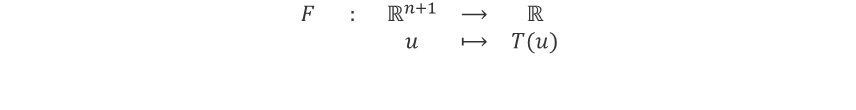

**Implementación**

Para la implementación, se deben seguir los siguientes pasos:

- Calcular el gradiente de                               

- Calcular la curva óptima para los distintos valores de $n$, teniendo en cuenta que:


$$T_j {\left(u\right)}=\frac{1}{2\left(n+1\right)}\cdot {\left(u_{j+1} +u_j \right)}\sqrt{1+{\left(n+1\right)}^2 {{\left(u_{j+1} -u_j \right)}}^2 }$$


- El gradiente está formado por:


$$\nabla F{\left(u_0 ,u_1 ,\ldots,\ u_n \right)}={{\left[g_0 ,g_1 ,\ldots,g_n \right]}}^T$$


Donde:

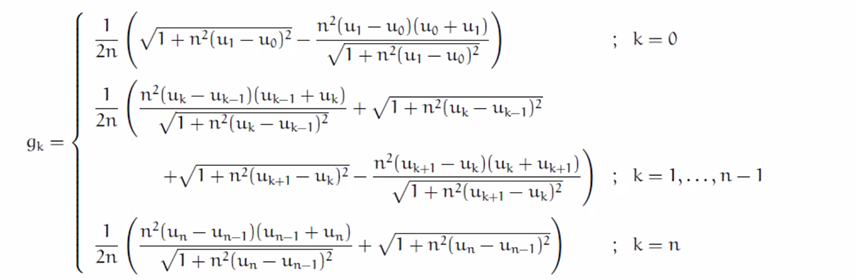

**Pautas de elaboración**

- Deberás determinar cuál es la curva tal que, al considerar su sólido de revolución, el área de superficie es mínima. Para hacerlo, ten en cuenta que la incógnita del problema es una función (es necesario discretizarla, como se explica en los apartados anteriores). Al discretizar, el problema se convierte en uno multidimensional de dimensión alta.

- El informe debe entregarse en formato PDF, donde sea posible discriminar cada uno de los aspectos listados en la tabla anexa para la rúbrica.

- Deberás entregar un fichero en `Matlab` que permita verificar los resultados. Es importante destacar que ese fichero debe correr directamente sin señalar error alguno.

**Calculamos optimización utilizando el método de paso fijo**

t1n1Iteracion:1
t1n1Iteracion:2
t1n1Iteracion:3
t1n1Iteracion:4
t1n1Iteracion:5
t1n1Iteracion:6
t1n1Iteracion:7
t1n1Iteracion:8
t1n1Iteracion:9
t1n1Iteracion:10
t1n1Iteracion:11
t1n1Iteracion:12
t1n1Iteracion:13
t1n1Iteracion:14
t1n1Iteracion:15
t1n1Iteracion:16
t1n1Iteracion:17
t1n1Iteracion:18
t1n1Iteracion:19
t1n1Iteracion:20
t1n1Iteracion:21
t1n1Iteracion:22
t1n1Iteracion:23
t1n1Iteracion:24
t1n1Iteracion:25
t1n1Iteracion:26
t1n1Iteracion:27
t1n1Iteracion:28
t1n1Iteracion:29
t1n1Iteracion:30
t1n1Iteracion:31
t1n1Iteracion:32
t1n1Iteracion:33
t1n1Iteracion:34
t1n1Iteracion:35
t1n1Iteracion:36
t1n1Iteracion:37
t1n1Iteracion:38
t1n1Iteracion:39
t1n1Iteracion:40
t1n1Iteracion:41
t1n1Iteracion:42
t1n1Iteracion:43
t1n1Iteracion:44
t1n1Iteracion:45
t1n1Iteracion:46
t1n1Iteracion:47
t1n1Iteracion:48
t1n1Iteracion:49
t1n1Iteracion:50
t1n1Iteracion:51
t1n1Iteracion:52
t1n1Iteracion:53
t1n1Iteracion:54
t1n1Iteracion:55
t1n1Iteracion:56
t1n1Iteracion:57
t1n1Iteracion:58
t1n1Iteracion:59
t1n1It

Área debajo de la curva (n=5, t_k=0.001): 0.94707


Resultados para n = 5, t_k = 0.001


Punto óptimo (x):


                         1         0.946623103144697         0.921053334698856         0.921053334698856         0.946623103144697                         1



Valor óptimo de f(x):


         0.809099771354379



Área debajo de la curva:


         0.947070575137421



Número de iteraciones:


        1000



Tiempo en segundos:


               250.8507063



t2n1Iteracion:1
t2n1Iteracion:2
t2n1Iteracion:3
t2n1Iteracion:4
t2n1Iteracion:5
t2n1Iteracion:6
t2n1Iteracion:7
t2n1Iteracion:8
t2n1Iteracion:9
t2n1Iteracion:10
t2n1Iteracion:11
t2n1Iteracion:12
t2n1Iteracion:13
t2n1Iteracion:14
t2n1Iteracion:15
t2n1Iteracion:16
t2n1Iteracion:17
t2n1Iteracion:18
t2n1Iteracion:19
t2n1Iteracion:20
t2n1Iteracion:21
t2n1Iteracion:22
t2n1Iteracion:23
t2n1Iteracion:24
t2n1Iteracion:25
t2n1Iteracion:26
t2n1Iteracion:27
t2n1Iteracion:28
t2n1Iteracion:29
t2n1Iteracion:30
t2n1Iteracion:31
t2n1Iteracion:32
t2n1Iteracion:33
t2n1Iteracion:34
t2n1Iteracion:35
t2n1Iteracion:36
t2n1Iteracion:37
t2n1Iteracion:38
t2n1Iteracion:39
t2n1Iteracion:40
t2n1Iteracion:41
t2n1Iteracion:42
t2n1Iteracion:43
t2n1Iteracion:44
t2n1Iteracion:45
t2n1Iteracion:46
t2n1Iteracion:47
t2n1Iteracion:48
t2n1Iteracion:49
t2n1Iteracion:50
t2n1Iteracion:51
t2n1Iteracion:52
t2n1Iteracion:53
t2n1Iteracion:54
t2n1Iteracion:55
t2n1Iteracion:56
t2n1Iteracion:57
t2n1Iteracion:58
t2n1Iteracion:59
t2n1It

Área debajo de la curva (n=5, t_k=0.01): 0.93733


Resultados para n = 5, t_k = 0.01


Punto óptimo (x):


                         1          0.93711661787847         0.906202236933189         0.906202236933189          0.93711661787847                         1



Valor óptimo de f(x):


          0.80856217060513



Área debajo de la curva:


         0.937327541924664



Número de iteraciones:


        1000



Tiempo en segundos:


               257.6271552



t3n1Iteracion:1
t3n1Iteracion:2
t3n1Iteracion:3
t3n1Iteracion:4
t3n1Iteracion:5
t3n1Iteracion:6
t3n1Iteracion:7
t3n1Iteracion:8
t3n1Iteracion:9
t3n1Iteracion:10
t3n1Iteracion:11
t3n1Iteracion:12
t3n1Iteracion:13
t3n1Iteracion:14
t3n1Iteracion:15
t3n1Iteracion:16
t3n1Iteracion:17
t3n1Iteracion:18
t3n1Iteracion:19
t3n1Iteracion:20
t3n1Iteracion:21
t3n1Iteracion:22
t3n1Iteracion:23
t3n1Iteracion:24
t3n1Iteracion:25
t3n1Iteracion:26
t3n1Iteracion:27
t3n1Iteracion:28
t3n1Iteracion:29
t3n1Iteracion:30
t3n1Iteracion:31
t3n1Iteracion:32
t3n1Iteracion:33
t3n1Iteracion:34
t3n1Iteracion:35
t3n1Iteracion:36
t3n1Iteracion:37
t3n1Iteracion:38
t3n1Iteracion:39
t3n1Iteracion:40
t3n1Iteracion:41
t3n1Iteracion:42
t3n1Iteracion:43
t3n1Iteracion:44
t3n1Iteracion:45
t3n1Iteracion:46
t3n1Iteracion:47
t3n1Iteracion:48
t3n1Iteracion:49
t3n1Iteracion:50
t3n1Iteracion:51
t3n1Iteracion:52
t3n1Iteracion:53
t3n1Iteracion:54
t3n1Iteracion:55
t3n1Iteracion:56
t3n1Iteracion:57
t3n1Iteracion:58
t3n1Iteracion:59
t3n1It

Área debajo de la curva (n=5, t_k=0.15): 0.89749


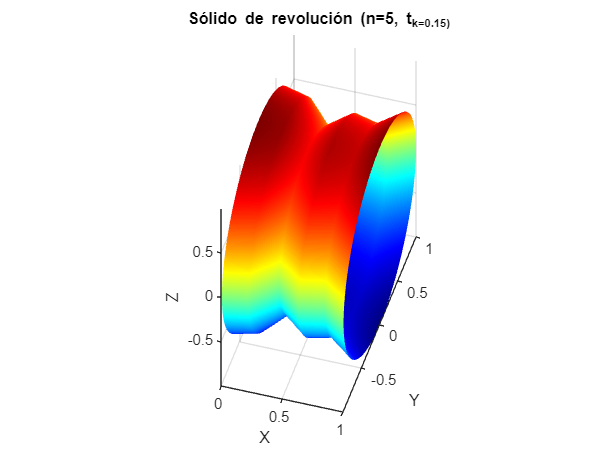

Resultados para n = 5, t_k = 0.15


Punto óptimo (x):


                         1         0.955695274217708          0.76222630362545          0.90586360803357         0.863674538177923                         1



Valor óptimo de f(x):


         0.924240618281357



Área debajo de la curva:


          0.89749194481093



Número de iteraciones:


        1000



Tiempo en segundos:


                235.860624



t1n2Iteracion:1
t1n2Iteracion:2
t1n2Iteracion:3
t1n2Iteracion:4
t1n2Iteracion:5
t1n2Iteracion:6
t1n2Iteracion:7
t1n2Iteracion:8
t1n2Iteracion:9
t1n2Iteracion:10
t1n2Iteracion:11
t1n2Iteracion:12
t1n2Iteracion:13
t1n2Iteracion:14
t1n2Iteracion:15
t1n2Iteracion:16
t1n2Iteracion:17
t1n2Iteracion:18
t1n2Iteracion:19
t1n2Iteracion:20
t1n2Iteracion:21
t1n2Iteracion:22
t1n2Iteracion:23
t1n2Iteracion:24
t1n2Iteracion:25
t1n2Iteracion:26
t1n2Iteracion:27
t1n2Iteracion:28
t1n2Iteracion:29
t1n2Iteracion:30
t1n2Iteracion:31
t1n2Iteracion:32
t1n2Iteracion:33
t1n2Iteracion:34
t1n2Iteracion:35
t1n2Iteracion:36
t1n2Iteracion:37
t1n2Iteracion:38
t1n2Iteracion:39
t1n2Iteracion:40
t1n2Iteracion:41
t1n2Iteracion:42
t1n2Iteracion:43
t1n2Iteracion:44
t1n2Iteracion:45
t1n2Iteracion:46
t1n2Iteracion:47
t1n2Iteracion:48
t1n2Iteracion:49
t1n2Iteracion:50
t1n2Iteracion:51
t1n2Iteracion:52
t1n2Iteracion:53
t1n2Iteracion:54
t1n2Iteracion:55
t1n2Iteracion:56
t1n2Iteracion:57
t1n2Iteracion:58
t1n2Iteracion:59
t1n2It

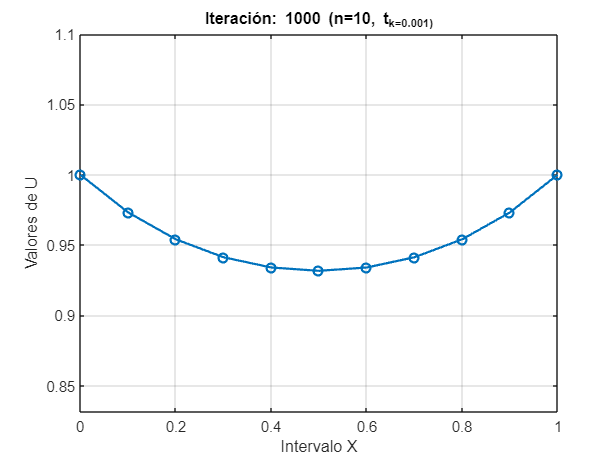

Área debajo de la curva (n=10, t_k=0.001): 0.95366


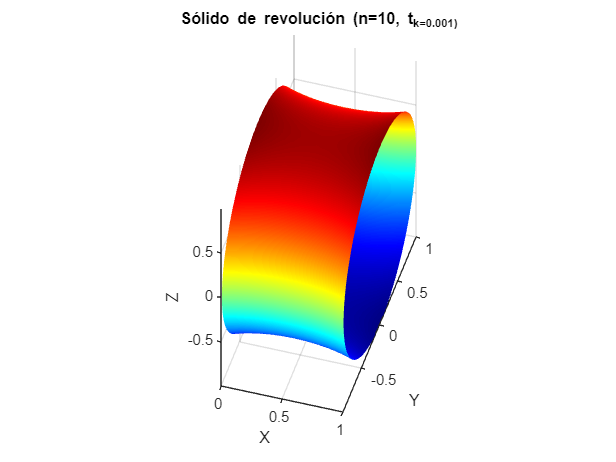

Resultados para n = 10, t_k = 0.001


Punto óptimo (x):


                         1         0.973201329112676         0.954040226950191         0.941271457453315          0.93398531623934         0.931620161166237          0.93398531623934         0.941271457453315         0.954040226950191         0.973201329112676                         1



Valor óptimo de f(x):


         0.880741578300841



Área debajo de la curva:


         0.953661682067728



Número de iteraciones:


        1000



Tiempo en segundos:


               242.4132353



t2n2Iteracion:1
t2n2Iteracion:2
t2n2Iteracion:3
t2n2Iteracion:4
t2n2Iteracion:5
t2n2Iteracion:6
t2n2Iteracion:7
t2n2Iteracion:8
t2n2Iteracion:9
t2n2Iteracion:10
t2n2Iteracion:11
t2n2Iteracion:12
t2n2Iteracion:13
t2n2Iteracion:14
t2n2Iteracion:15
t2n2Iteracion:16
t2n2Iteracion:17
t2n2Iteracion:18
t2n2Iteracion:19
t2n2Iteracion:20
t2n2Iteracion:21
t2n2Iteracion:22
t2n2Iteracion:23
t2n2Iteracion:24
t2n2Iteracion:25
t2n2Iteracion:26
t2n2Iteracion:27
t2n2Iteracion:28
t2n2Iteracion:29
t2n2Iteracion:30
t2n2Iteracion:31
t2n2Iteracion:32
t2n2Iteracion:33
t2n2Iteracion:34
t2n2Iteracion:35
t2n2Iteracion:36
t2n2Iteracion:37
t2n2Iteracion:38
t2n2Iteracion:39
t2n2Iteracion:40
t2n2Iteracion:41
t2n2Iteracion:42
t2n2Iteracion:43
t2n2Iteracion:44
t2n2Iteracion:45
t2n2Iteracion:46
t2n2Iteracion:47
t2n2Iteracion:48
t2n2Iteracion:49
t2n2Iteracion:50
t2n2Iteracion:51
t2n2Iteracion:52
t2n2Iteracion:53
t2n2Iteracion:54
t2n2Iteracion:55
t2n2Iteracion:56
t2n2Iteracion:57
t2n2Iteracion:58
t2n2Iteracion:59
t2n2It

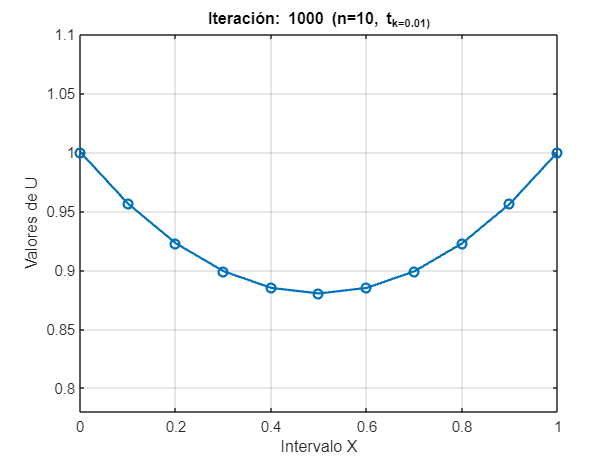

Área debajo de la curva (n=10, t_k=0.01): 0.92057


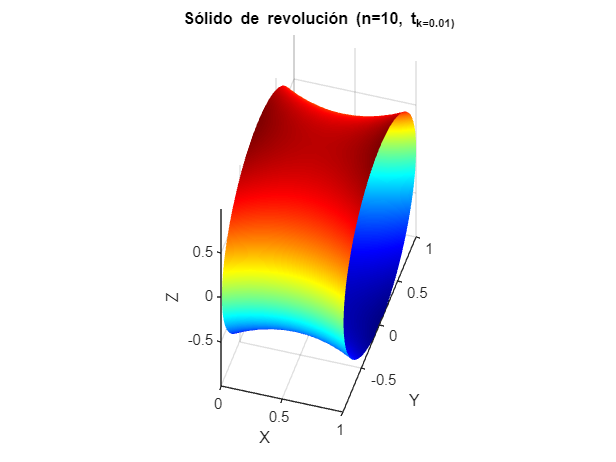

Resultados para n = 10, t_k = 0.01


Punto óptimo (x):


                         1         0.956247615732554         0.922694149103687         0.898980486542834          0.88485296282583         0.880160510813889          0.88485296282583         0.898980486542834         0.922694149103687         0.956247615732554                         1



Valor óptimo de f(x):


         0.875372177019642



Área debajo de la curva:


          0.92057109392237



Número de iteraciones:


        1000



Tiempo en segundos:


               241.7902683



t3n2Iteracion:1
t3n2Iteracion:2
t3n2Iteracion:3
t3n2Iteracion:4
t3n2Iteracion:5
t3n2Iteracion:6
t3n2Iteracion:7
t3n2Iteracion:8
t3n2Iteracion:9
t3n2Iteracion:10
t3n2Iteracion:11
t3n2Iteracion:12
t3n2Iteracion:13
t3n2Iteracion:14
t3n2Iteracion:15
t3n2Iteracion:16
t3n2Iteracion:17
t3n2Iteracion:18
t3n2Iteracion:19
t3n2Iteracion:20
t3n2Iteracion:21
t3n2Iteracion:22
t3n2Iteracion:23
t3n2Iteracion:24
t3n2Iteracion:25
t3n2Iteracion:26
t3n2Iteracion:27
t3n2Iteracion:28
t3n2Iteracion:29
t3n2Iteracion:30
t3n2Iteracion:31
t3n2Iteracion:32
t3n2Iteracion:33
t3n2Iteracion:34
t3n2Iteracion:35
t3n2Iteracion:36
t3n2Iteracion:37
t3n2Iteracion:38
t3n2Iteracion:39
t3n2Iteracion:40
t3n2Iteracion:41
t3n2Iteracion:42
t3n2Iteracion:43
t3n2Iteracion:44
t3n2Iteracion:45
t3n2Iteracion:46
t3n2Iteracion:47
t3n2Iteracion:48
t3n2Iteracion:49
t3n2Iteracion:50
t3n2Iteracion:51
t3n2Iteracion:52
t3n2Iteracion:53
t3n2Iteracion:54
t3n2Iteracion:55
t3n2Iteracion:56
t3n2Iteracion:57
t3n2Iteracion:58
t3n2Iteracion:59
t3n2It

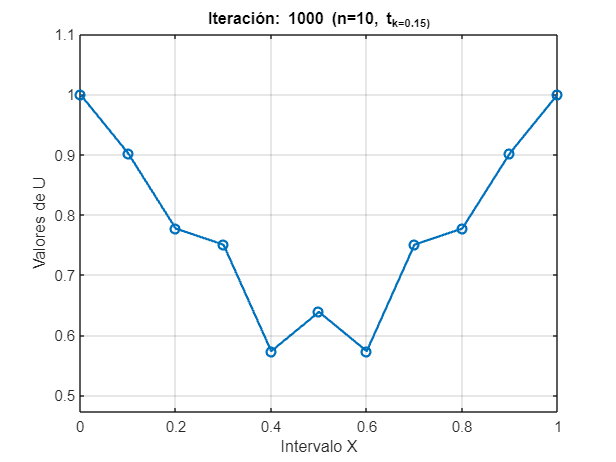

Área debajo de la curva (n=10, t_k=0.15): 0.7645


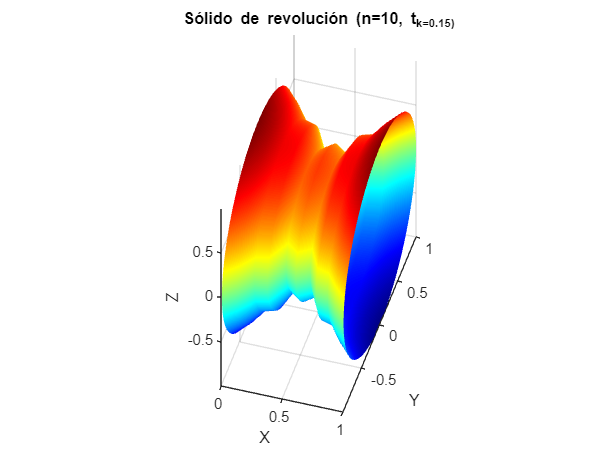

Resultados para n = 10, t_k = 0.15


Punto óptimo (x):


                         1          0.90234736076186         0.777036619577393         0.750303476892444         0.573491183416285         0.638615012831444         0.573491183416285         0.750303476892444         0.777036619577393          0.90234736076186                         1



Valor óptimo de f(x):


           1.0572647386375



Área debajo de la curva:


         0.764497229412741



Número de iteraciones:


        1000



Tiempo en segundos:


               245.1601991



t1n3Iteracion:1
t1n3Iteracion:2
t1n3Iteracion:3
t1n3Iteracion:4
t1n3Iteracion:5
t1n3Iteracion:6
t1n3Iteracion:7
t1n3Iteracion:8
t1n3Iteracion:9
t1n3Iteracion:10
t1n3Iteracion:11
t1n3Iteracion:12
t1n3Iteracion:13
t1n3Iteracion:14
t1n3Iteracion:15
t1n3Iteracion:16
t1n3Iteracion:17
t1n3Iteracion:18
t1n3Iteracion:19
t1n3Iteracion:20
t1n3Iteracion:21
t1n3Iteracion:22
t1n3Iteracion:23
t1n3Iteracion:24
t1n3Iteracion:25
t1n3Iteracion:26
t1n3Iteracion:27
t1n3Iteracion:28
t1n3Iteracion:29
t1n3Iteracion:30
t1n3Iteracion:31
t1n3Iteracion:32
t1n3Iteracion:33
t1n3Iteracion:34
t1n3Iteracion:35
t1n3Iteracion:36
t1n3Iteracion:37
t1n3Iteracion:38
t1n3Iteracion:39
t1n3Iteracion:40
t1n3Iteracion:41
t1n3Iteracion:42
t1n3Iteracion:43
t1n3Iteracion:44
t1n3Iteracion:45
t1n3Iteracion:46
t1n3Iteracion:47
t1n3Iteracion:48
t1n3Iteracion:49
t1n3Iteracion:50
t1n3Iteracion:51
t1n3Iteracion:52
t1n3Iteracion:53
t1n3Iteracion:54
t1n3Iteracion:55
t1n3Iteracion:56
t1n3Iteracion:57
t1n3Iteracion:58
t1n3Iteracion:59
t1n3It

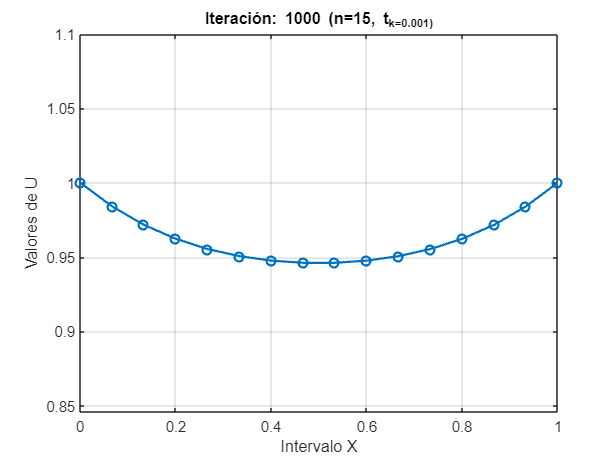

Área debajo de la curva (n=15, t_k=0.001): 0.96236


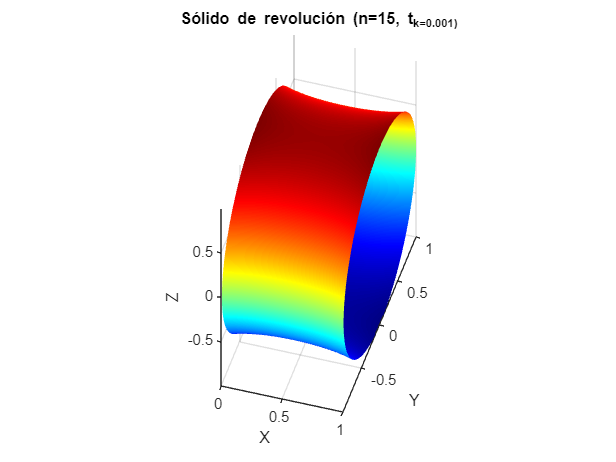

Resultados para n = 15, t_k = 0.001


Punto óptimo (x):


                         1         0.984046060974193         0.971661947350133         0.962274047714829         0.955390212922757         0.950601991179369            0.947591960868         0.946142380570906         0.946142380570906            0.947591960868         0.950601991179369         0.955390212922757         0.962274047714829         0.971661947350133         0.984046060974193                         1



Valor óptimo de f(x):


         0.911165349205603



Área debajo de la curva:


         0.962361146877358



Número de iteraciones:


        1000



Tiempo en segundos:


               247.8748232



t2n3Iteracion:1
t2n3Iteracion:2
t2n3Iteracion:3
t2n3Iteracion:4
t2n3Iteracion:5
t2n3Iteracion:6
t2n3Iteracion:7
t2n3Iteracion:8
t2n3Iteracion:9
t2n3Iteracion:10
t2n3Iteracion:11
t2n3Iteracion:12
t2n3Iteracion:13
t2n3Iteracion:14
t2n3Iteracion:15
t2n3Iteracion:16
t2n3Iteracion:17
t2n3Iteracion:18
t2n3Iteracion:19
t2n3Iteracion:20
t2n3Iteracion:21
t2n3Iteracion:22
t2n3Iteracion:23
t2n3Iteracion:24
t2n3Iteracion:25
t2n3Iteracion:26
t2n3Iteracion:27
t2n3Iteracion:28
t2n3Iteracion:29
t2n3Iteracion:30
t2n3Iteracion:31
t2n3Iteracion:32
t2n3Iteracion:33
t2n3Iteracion:34
t2n3Iteracion:35
t2n3Iteracion:36
t2n3Iteracion:37
t2n3Iteracion:38
t2n3Iteracion:39
t2n3Iteracion:40
t2n3Iteracion:41
t2n3Iteracion:42
t2n3Iteracion:43
t2n3Iteracion:44
t2n3Iteracion:45
t2n3Iteracion:46
t2n3Iteracion:47
t2n3Iteracion:48
t2n3Iteracion:49
t2n3Iteracion:50
t2n3Iteracion:51
t2n3Iteracion:52
t2n3Iteracion:53
t2n3Iteracion:54
t2n3Iteracion:55
t2n3Iteracion:56
t2n3Iteracion:57
t2n3Iteracion:58
t2n3Iteracion:59
t2n3It

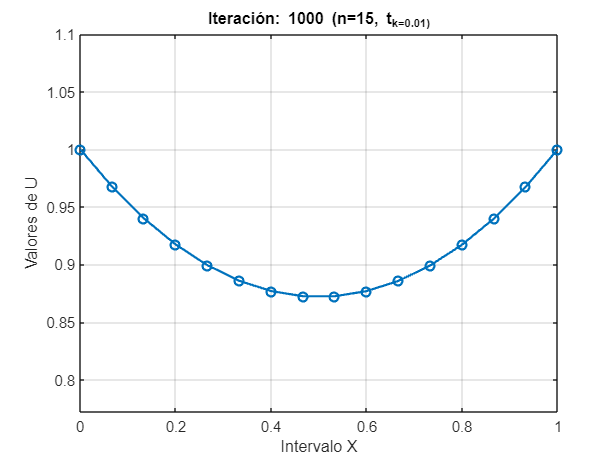

Área debajo de la curva (n=15, t_k=0.01): 0.91454


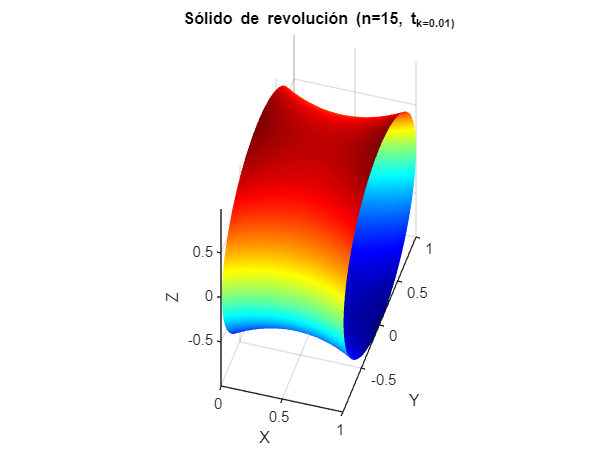

Resultados para n = 15, t_k = 0.01


Punto óptimo (x):


                         1          0.96751306002578         0.939983328999789         0.917262526640313         0.899229037352288         0.885786838752868         0.876864649465864         0.872415296263327         0.872415296263327         0.876864649465864         0.885786838752868         0.899229037352288         0.917262526640313         0.939983328999789          0.96751306002578                         1



Valor óptimo de f(x):


         0.900063244797155



Área debajo de la curva:


         0.914540631666697



Número de iteraciones:


        1000



Tiempo en segundos:


               248.7773588



t3n3Iteracion:1
t3n3Iteracion:2
t3n3Iteracion:3
t3n3Iteracion:4
t3n3Iteracion:5
t3n3Iteracion:6
t3n3Iteracion:7
t3n3Iteracion:8
t3n3Iteracion:9
t3n3Iteracion:10
t3n3Iteracion:11
t3n3Iteracion:12
t3n3Iteracion:13
t3n3Iteracion:14
t3n3Iteracion:15
t3n3Iteracion:16
t3n3Iteracion:17
t3n3Iteracion:18
t3n3Iteracion:19
t3n3Iteracion:20
t3n3Iteracion:21
t3n3Iteracion:22
t3n3Iteracion:23
t3n3Iteracion:24
t3n3Iteracion:25
t3n3Iteracion:26
t3n3Iteracion:27
t3n3Iteracion:28
t3n3Iteracion:29
t3n3Iteracion:30
t3n3Iteracion:31
t3n3Iteracion:32
t3n3Iteracion:33
t3n3Iteracion:34
t3n3Iteracion:35
t3n3Iteracion:36
t3n3Iteracion:37
t3n3Iteracion:38
t3n3Iteracion:39
t3n3Iteracion:40
t3n3Iteracion:41
t3n3Iteracion:42
t3n3Iteracion:43
t3n3Iteracion:44
t3n3Iteracion:45
t3n3Iteracion:46
t3n3Iteracion:47
t3n3Iteracion:48
t3n3Iteracion:49
t3n3Iteracion:50
t3n3Iteracion:51
t3n3Iteracion:52
t3n3Iteracion:53
t3n3Iteracion:54
t3n3Iteracion:55
t3n3Iteracion:56
t3n3Iteracion:57
t3n3Iteracion:58
t3n3Iteracion:59
t3n3It

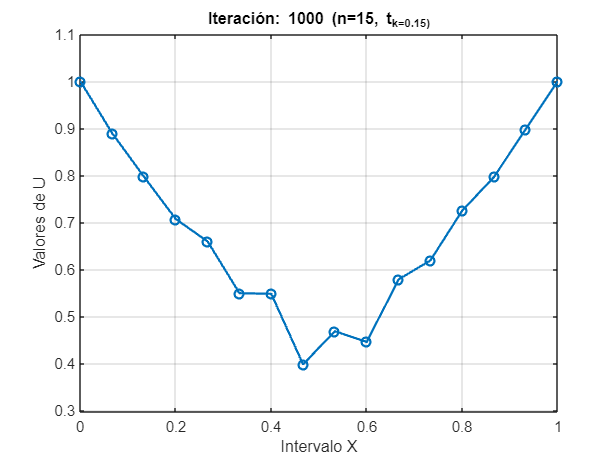

Área debajo de la curva (n=15, t_k=0.15): 0.67172


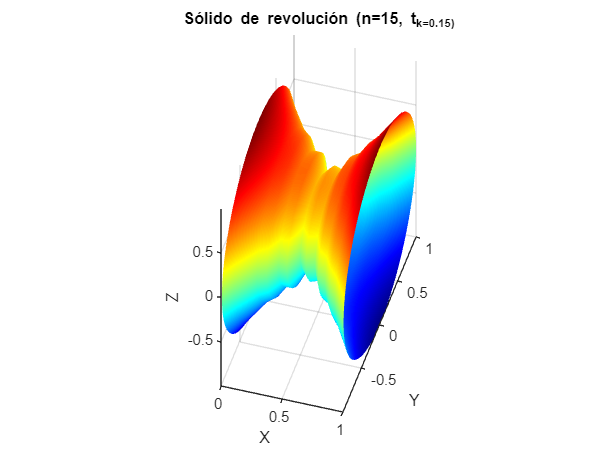

Resultados para n = 15, t_k = 0.15


Punto óptimo (x):


                         1         0.889449704469299          0.79672277835801         0.706660138227207         0.659069073277879         0.549027675283843         0.547704747135792         0.397630045877896         0.468272789555412         0.445232605644323         0.578269713157046          0.61875898680293         0.724547038474344           0.7963048816564         0.898077245868419                         1



Valor óptimo de f(x):


          1.09845462824077



Área debajo de la curva:


          0.67171516158592



Número de iteraciones:


        1000



Tiempo en segundos:


               249.2522017



t1n4Iteracion:1
t1n4Iteracion:2
t1n4Iteracion:3
t1n4Iteracion:4
t1n4Iteracion:5
t1n4Iteracion:6
t1n4Iteracion:7
t1n4Iteracion:8
t1n4Iteracion:9
t1n4Iteracion:10
t1n4Iteracion:11
t1n4Iteracion:12
t1n4Iteracion:13
t1n4Iteracion:14
t1n4Iteracion:15
t1n4Iteracion:16
t1n4Iteracion:17
t1n4Iteracion:18
t1n4Iteracion:19
t1n4Iteracion:20
t1n4Iteracion:21
t1n4Iteracion:22
t1n4Iteracion:23
t1n4Iteracion:24
t1n4Iteracion:25
t1n4Iteracion:26
t1n4Iteracion:27
t1n4Iteracion:28
t1n4Iteracion:29
t1n4Iteracion:30
t1n4Iteracion:31
t1n4Iteracion:32
t1n4Iteracion:33
t1n4Iteracion:34
t1n4Iteracion:35
t1n4Iteracion:36
t1n4Iteracion:37
t1n4Iteracion:38
t1n4Iteracion:39
t1n4Iteracion:40
t1n4Iteracion:41
t1n4Iteracion:42
t1n4Iteracion:43
t1n4Iteracion:44
t1n4Iteracion:45
t1n4Iteracion:46
t1n4Iteracion:47
t1n4Iteracion:48
t1n4Iteracion:49
t1n4Iteracion:50
t1n4Iteracion:51
t1n4Iteracion:52
t1n4Iteracion:53
t1n4Iteracion:54
t1n4Iteracion:55
t1n4Iteracion:56
t1n4Iteracion:57
t1n4Iteracion:58
t1n4Iteracion:59
t1n4It

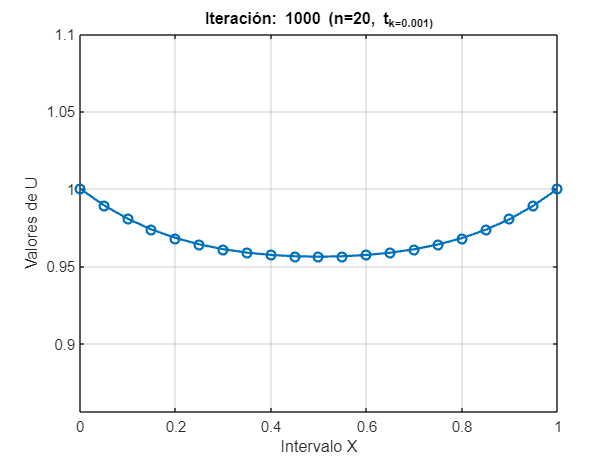

Área debajo de la curva (n=20, t_k=0.001): 0.9687


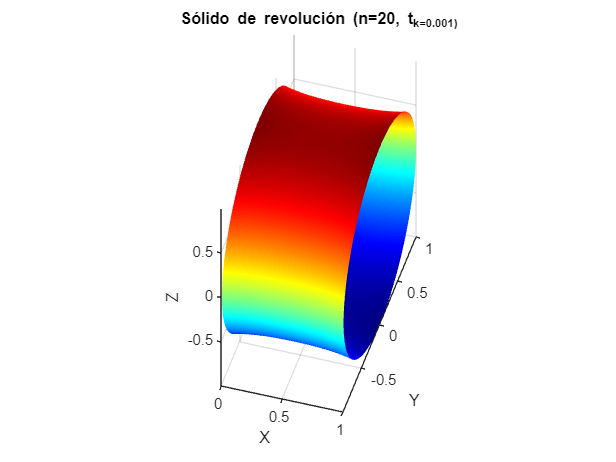

Resultados para n = 20, t_k = 0.001


Punto óptimo (x):


                         1         0.989221620684772         0.980522816595261         0.973603046471446         0.968190624246545         0.964043169378534          0.96094957158541         0.958732594437754         0.957251469478314         0.956404076844506         0.956128523637608         0.956404076844506         0.957251469478314         0.958732594437754          0.96094957158541         0.964043169378534         0.968190624246545         0.973603046471446         0.980522816595261         0.989221620684772                         1



Valor óptimo de f(x):


         0.928791560555013



Área debajo de la curva:


         0.968698325154134



Número de iteraciones:


        1000



Tiempo en segundos:


               250.8317308



t2n4Iteracion:1
t2n4Iteracion:2
t2n4Iteracion:3
t2n4Iteracion:4
t2n4Iteracion:5
t2n4Iteracion:6
t2n4Iteracion:7
t2n4Iteracion:8
t2n4Iteracion:9
t2n4Iteracion:10
t2n4Iteracion:11
t2n4Iteracion:12
t2n4Iteracion:13
t2n4Iteracion:14
t2n4Iteracion:15
t2n4Iteracion:16
t2n4Iteracion:17
t2n4Iteracion:18
t2n4Iteracion:19
t2n4Iteracion:20
t2n4Iteracion:21
t2n4Iteracion:22
t2n4Iteracion:23
t2n4Iteracion:24
t2n4Iteracion:25
t2n4Iteracion:26
t2n4Iteracion:27
t2n4Iteracion:28
t2n4Iteracion:29
t2n4Iteracion:30
t2n4Iteracion:31
t2n4Iteracion:32
t2n4Iteracion:33
t2n4Iteracion:34
t2n4Iteracion:35
t2n4Iteracion:36
t2n4Iteracion:37
t2n4Iteracion:38
t2n4Iteracion:39
t2n4Iteracion:40
t2n4Iteracion:41
t2n4Iteracion:42
t2n4Iteracion:43
t2n4Iteracion:44
t2n4Iteracion:45
t2n4Iteracion:46
t2n4Iteracion:47
t2n4Iteracion:48
t2n4Iteracion:49
t2n4Iteracion:50
t2n4Iteracion:51
t2n4Iteracion:52
t2n4Iteracion:53
t2n4Iteracion:54
t2n4Iteracion:55
t2n4Iteracion:56
t2n4Iteracion:57
t2n4Iteracion:58
t2n4Iteracion:59
t2n4It

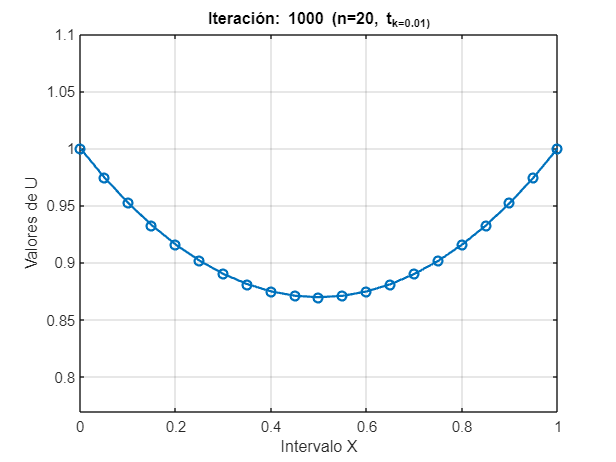

Área debajo de la curva (n=20, t_k=0.01): 0.91275


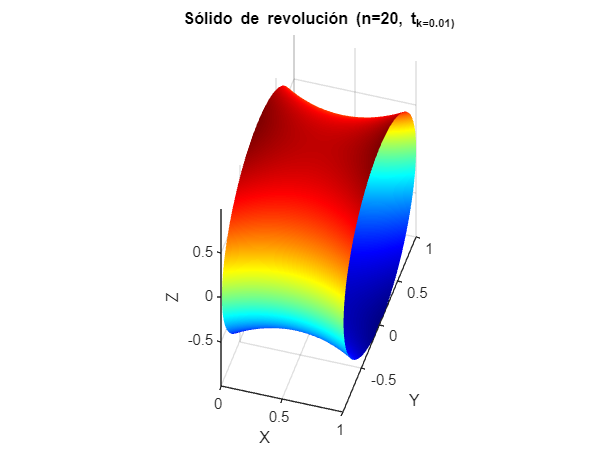

Resultados para n = 20, t_k = 0.01


Punto óptimo (x):


                         1         0.974643747224123         0.952184855687726         0.932544403129411         0.915654431028547         0.901457304261808         0.889905160377619         0.880959449780922         0.874590565327292         0.870777558571805         0.869507939694462         0.870777558571805         0.874590565327292         0.880959449780922         0.889905160377619         0.901457304261808         0.915654431028547         0.932544403129411         0.952184855687726         0.974643747224123                         1



Valor óptimo de f(x):


         0.912934875439954



Área debajo de la curva:


         0.912747144523648



Número de iteraciones:


        1000



Tiempo en segundos:


               249.9751515



t3n4Iteracion:1
t3n4Iteracion:2
t3n4Iteracion:3
t3n4Iteracion:4
t3n4Iteracion:5
t3n4Iteracion:6
t3n4Iteracion:7
t3n4Iteracion:8
t3n4Iteracion:9
t3n4Iteracion:10
t3n4Iteracion:11
t3n4Iteracion:12
t3n4Iteracion:13
t3n4Iteracion:14
t3n4Iteracion:15
t3n4Iteracion:16
t3n4Iteracion:17
t3n4Iteracion:18
t3n4Iteracion:19
t3n4Iteracion:20
t3n4Iteracion:21
t3n4Iteracion:22
t3n4Iteracion:23
t3n4Iteracion:24
t3n4Iteracion:25
t3n4Iteracion:26
t3n4Iteracion:27
t3n4Iteracion:28
t3n4Iteracion:29
t3n4Iteracion:30
t3n4Iteracion:31
t3n4Iteracion:32
t3n4Iteracion:33
t3n4Iteracion:34
t3n4Iteracion:35
t3n4Iteracion:36
t3n4Iteracion:37
t3n4Iteracion:38
t3n4Iteracion:39
t3n4Iteracion:40
t3n4Iteracion:41
t3n4Iteracion:42
t3n4Iteracion:43
t3n4Iteracion:44
t3n4Iteracion:45
t3n4Iteracion:46
t3n4Iteracion:47
t3n4Iteracion:48
t3n4Iteracion:49
t3n4Iteracion:50
t3n4Iteracion:51
t3n4Iteracion:52
t3n4Iteracion:53
t3n4Iteracion:54
t3n4Iteracion:55
t3n4Iteracion:56
t3n4Iteracion:57
t3n4Iteracion:58
t3n4Iteracion:59
t3n4It

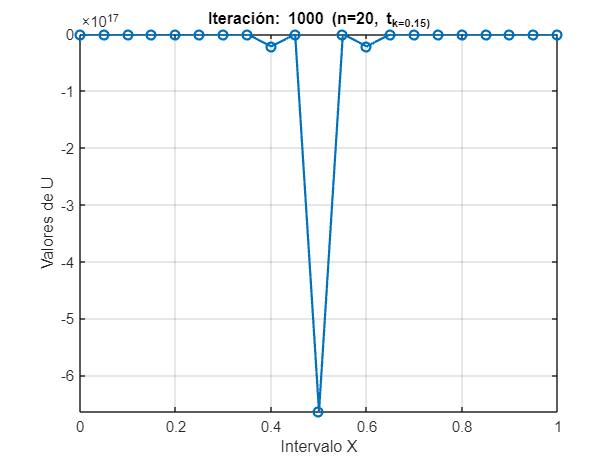

Área debajo de la curva (n=20, t_k=0.15): -3.535221222600653e+16


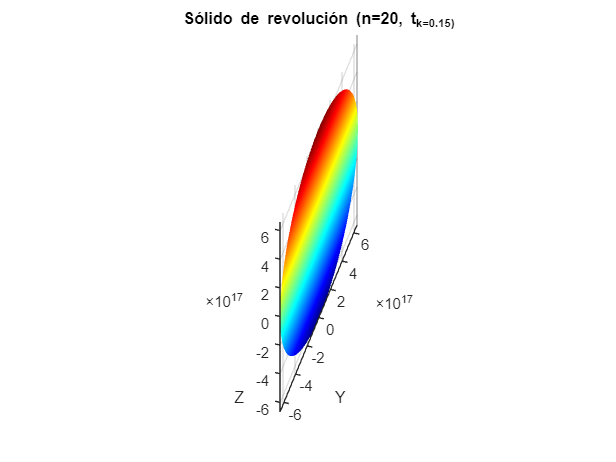

Resultados para n = 20, t_k = 0.15


Punto óptimo (x):


                         1         0.692497976562336         0.442936193251793         0.228793884942896        0.0406460709785055       -0.0506147129966143         -110129264197.305        -0.234228396542357     -2.17324456153496e+16         -15.3227337244612     -6.63579133030903e+17          -13.773774074778     -2.17324456153495e+16         0.200031186773385         -110129264196.921       -0.0506137449556924         0.040646064681703         0.228793884717229         0.442936193240218         0.692497976561813                         1



Valor óptimo de f(x):


     -4.41281864178917e+35



Área debajo de la curva:


     -3.53522122260065e+16



Número de iteraciones:


        1000



Tiempo en segundos:


               250.2156603



t1n5Iteracion:1
t1n5Iteracion:2
t1n5Iteracion:3
t1n5Iteracion:4
t1n5Iteracion:5
t1n5Iteracion:6
t1n5Iteracion:7
t1n5Iteracion:8
t1n5Iteracion:9
t1n5Iteracion:10
t1n5Iteracion:11
t1n5Iteracion:12
t1n5Iteracion:13
t1n5Iteracion:14
t1n5Iteracion:15
t1n5Iteracion:16
t1n5Iteracion:17
t1n5Iteracion:18
t1n5Iteracion:19
t1n5Iteracion:20
t1n5Iteracion:21
t1n5Iteracion:22
t1n5Iteracion:23
t1n5Iteracion:24
t1n5Iteracion:25
t1n5Iteracion:26
t1n5Iteracion:27
t1n5Iteracion:28
t1n5Iteracion:29
t1n5Iteracion:30
t1n5Iteracion:31
t1n5Iteracion:32
t1n5Iteracion:33
t1n5Iteracion:34
t1n5Iteracion:35
t1n5Iteracion:36
t1n5Iteracion:37
t1n5Iteracion:38
t1n5Iteracion:39
t1n5Iteracion:40
t1n5Iteracion:41
t1n5Iteracion:42
t1n5Iteracion:43
t1n5Iteracion:44
t1n5Iteracion:45
t1n5Iteracion:46
t1n5Iteracion:47
t1n5Iteracion:48
t1n5Iteracion:49
t1n5Iteracion:50
t1n5Iteracion:51
t1n5Iteracion:52
t1n5Iteracion:53
t1n5Iteracion:54
t1n5Iteracion:55
t1n5Iteracion:56
t1n5Iteracion:57
t1n5Iteracion:58
t1n5Iteracion:59
t1n5It

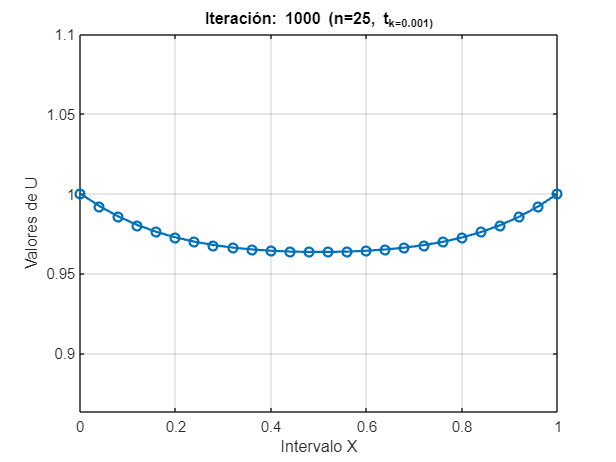

Área debajo de la curva (n=25, t_k=0.001): 0.97328


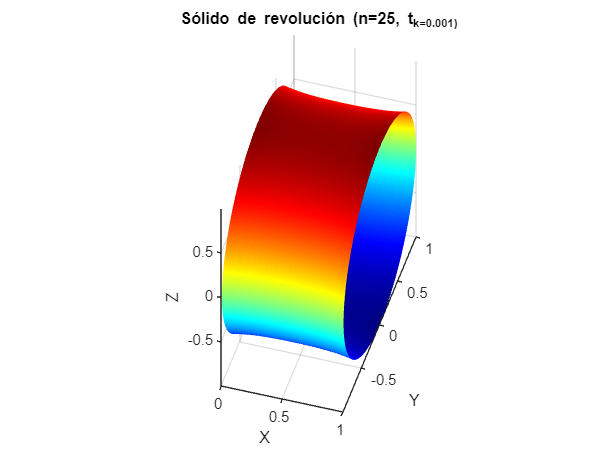

Resultados para n = 25, t_k = 0.001


Punto óptimo (x):


                         1         0.992108640358936         0.985581415336886          0.98024162165387         0.975925579998195         0.972482927522278           0.9697774006299         0.967687813479314         0.966109006003583          0.96495261687012         0.964147619491363         0.963640629118267         0.963396035667467         0.963396035667467         0.963640629118267         0.964147619491363          0.96495261687012         0.966109006003583         0.967687813479314           0.9697774006299         0.972482927522278         0.975925579998195          0.98024162165387         0.985581415336886         0.992108640358936                         1



Valor óptimo de f(x):


         0.940445706343614



Área debajo de la curva:


         0.973284104490414



Número de iteraciones:


        1000



Tiempo en segundos:


               253.0940796



t2n5Iteracion:1
t2n5Iteracion:2
t2n5Iteracion:3
t2n5Iteracion:4
t2n5Iteracion:5
t2n5Iteracion:6
t2n5Iteracion:7
t2n5Iteracion:8
t2n5Iteracion:9
t2n5Iteracion:10
t2n5Iteracion:11
t2n5Iteracion:12
t2n5Iteracion:13
t2n5Iteracion:14
t2n5Iteracion:15
t2n5Iteracion:16
t2n5Iteracion:17
t2n5Iteracion:18
t2n5Iteracion:19
t2n5Iteracion:20
t2n5Iteracion:21
t2n5Iteracion:22
t2n5Iteracion:23
t2n5Iteracion:24
t2n5Iteracion:25
t2n5Iteracion:26
t2n5Iteracion:27
t2n5Iteracion:28
t2n5Iteracion:29
t2n5Iteracion:30
t2n5Iteracion:31
t2n5Iteracion:32
t2n5Iteracion:33
t2n5Iteracion:34
t2n5Iteracion:35
t2n5Iteracion:36
t2n5Iteracion:37
t2n5Iteracion:38
t2n5Iteracion:39
t2n5Iteracion:40
t2n5Iteracion:41
t2n5Iteracion:42
t2n5Iteracion:43
t2n5Iteracion:44
t2n5Iteracion:45
t2n5Iteracion:46
t2n5Iteracion:47
t2n5Iteracion:48
t2n5Iteracion:49
t2n5Iteracion:50
t2n5Iteracion:51
t2n5Iteracion:52
t2n5Iteracion:53
t2n5Iteracion:54
t2n5Iteracion:55
t2n5Iteracion:56
t2n5Iteracion:57
t2n5Iteracion:58
t2n5Iteracion:59
t2n5It

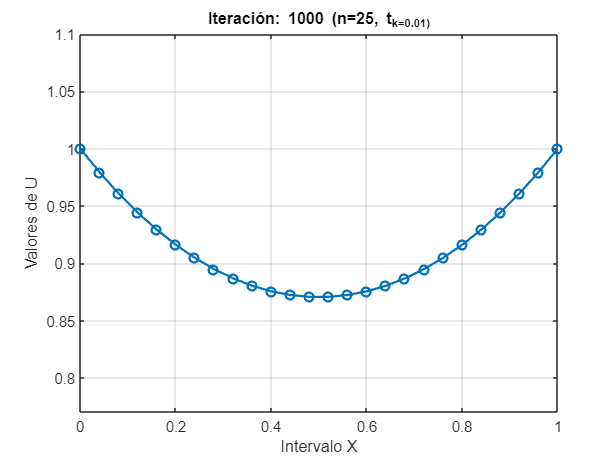

Área debajo de la curva (n=25, t_k=0.01): 0.91324


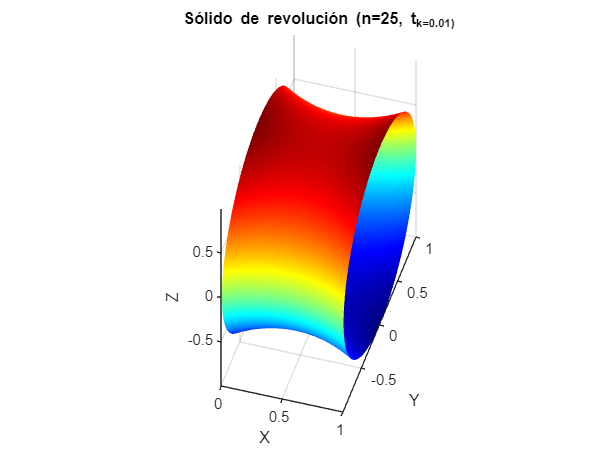

Resultados para n = 25, t_k = 0.01


Punto óptimo (x):


                         1          0.97956084974197         0.961003352925263         0.944278077461428         0.929341426451964         0.916155239894199         0.904686441974628         0.894906733581446         0.886792328747151         0.880323733288703         0.875485563789933         0.872266405161502         0.870658705244448         0.870658705244448         0.872266405161502         0.875485563789933         0.880323733288703         0.886792328747151         0.894906733581446         0.904686441974628         0.916155239894199         0.929341426451964         0.944278077461428         0.961003352925263          0.97956084974197                         1



Valor óptimo de f(x):


         0.920895319825129



Área debajo de la curva:


         0.913236708661011



Número de iteraciones:


        1000



Tiempo en segundos:


               247.8574195



t3n5Iteracion:1
t3n5Iteracion:2
t3n5Iteracion:3
t3n5Iteracion:4
t3n5Iteracion:5
t3n5Iteracion:6
t3n5Iteracion:7
t3n5Iteracion:8
t3n5Iteracion:9
t3n5Iteracion:10
t3n5Iteracion:11
t3n5Iteracion:12
t3n5Iteracion:13
t3n5Iteracion:14
t3n5Iteracion:15
t3n5Iteracion:16
t3n5Iteracion:17
t3n5Iteracion:18
t3n5Iteracion:19
t3n5Iteracion:20
t3n5Iteracion:21
t3n5Iteracion:22
t3n5Iteracion:23
t3n5Iteracion:24
t3n5Iteracion:25
t3n5Iteracion:26
t3n5Iteracion:27
t3n5Iteracion:28
t3n5Iteracion:29
t3n5Iteracion:30
t3n5Iteracion:31
t3n5Iteracion:32
t3n5Iteracion:33
t3n5Iteracion:34
t3n5Iteracion:35
t3n5Iteracion:36
t3n5Iteracion:37
t3n5Iteracion:38
t3n5Iteracion:39
t3n5Iteracion:40
t3n5Iteracion:41
t3n5Iteracion:42
t3n5Iteracion:43
t3n5Iteracion:44
t3n5Iteracion:45
t3n5Iteracion:46
t3n5Iteracion:47
t3n5Iteracion:48
t3n5Iteracion:49
t3n5Iteracion:50
t3n5Iteracion:51
t3n5Iteracion:52
t3n5Iteracion:53
t3n5Iteracion:54
t3n5Iteracion:55
t3n5Iteracion:56
t3n5Iteracion:57
t3n5Iteracion:58
t3n5Iteracion:59
t3n5It

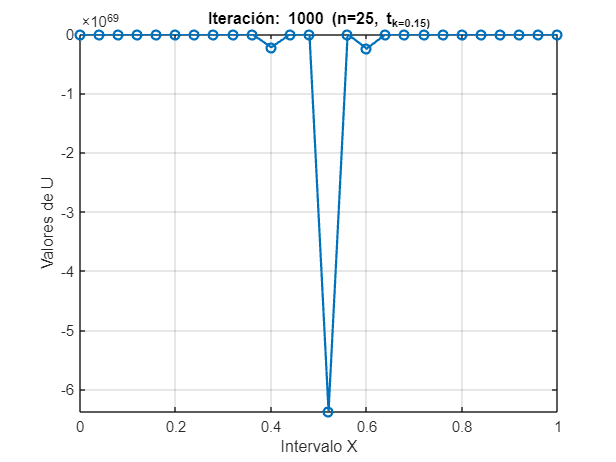

Área debajo de la curva (n=25, t_k=0.15): -2.737623908413613e+68


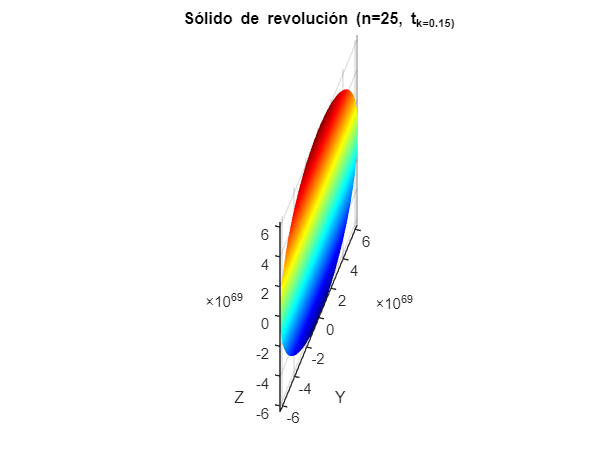

Resultados para n = 25, t_k = 0.15


Punto óptimo (x):


                         1           1.1197618561642          1.27520403911673         -6.03048099573143      8.16291655843915e+17      4.49101760269507e+34     -1.75625730763453e+52     -4.75211350700282e+46     -3.99703788693564e+63     -1.80947892367027e+51     -2.24234651221357e+68     -2.13108986820122e+51      1.72592066543137e+52     -6.37436908661845e+69      3.67526492640283e+52     -2.45447857539506e+68       1.3115156717627e+51      -4.1786168296266e+63      8.30209821002404e+45     -1.87790767490865e+52      1.14656739386278e+35      1.78641666042522e+18          10.6676298552166         0.757349120887334         0.884662362179852                         1



Valor óptimo de f(x):


    -4.07431070820495e+139



Área debajo de la curva:


     -2.73762390841361e+68



Número de iteraciones:


        1000



Tiempo en segundos:


               258.0157023



t1n6Iteracion:1
t1n6Iteracion:2
t1n6Iteracion:3
t1n6Iteracion:4
t1n6Iteracion:5
t1n6Iteracion:6
t1n6Iteracion:7
t1n6Iteracion:8
t1n6Iteracion:9
t1n6Iteracion:10
t1n6Iteracion:11
t1n6Iteracion:12
t1n6Iteracion:13
t1n6Iteracion:14
t1n6Iteracion:15
t1n6Iteracion:16
t1n6Iteracion:17
t1n6Iteracion:18
t1n6Iteracion:19
t1n6Iteracion:20
t1n6Iteracion:21
t1n6Iteracion:22
t1n6Iteracion:23
t1n6Iteracion:24
t1n6Iteracion:25
t1n6Iteracion:26
t1n6Iteracion:27
t1n6Iteracion:28
t1n6Iteracion:29
t1n6Iteracion:30
t1n6Iteracion:31
t1n6Iteracion:32
t1n6Iteracion:33
t1n6Iteracion:34
t1n6Iteracion:35
t1n6Iteracion:36
t1n6Iteracion:37
t1n6Iteracion:38
t1n6Iteracion:39
t1n6Iteracion:40
t1n6Iteracion:41
t1n6Iteracion:42
t1n6Iteracion:43
t1n6Iteracion:44
t1n6Iteracion:45
t1n6Iteracion:46
t1n6Iteracion:47
t1n6Iteracion:48
t1n6Iteracion:49
t1n6Iteracion:50
t1n6Iteracion:51
t1n6Iteracion:52
t1n6Iteracion:53
t1n6Iteracion:54
t1n6Iteracion:55
t1n6Iteracion:56
t1n6Iteracion:57
t1n6Iteracion:58
t1n6Iteracion:59
t1n6It

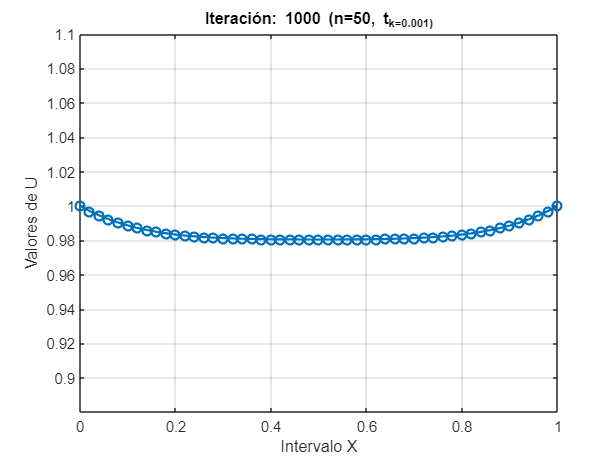

Área debajo de la curva (n=50, t_k=0.001): 0.98459


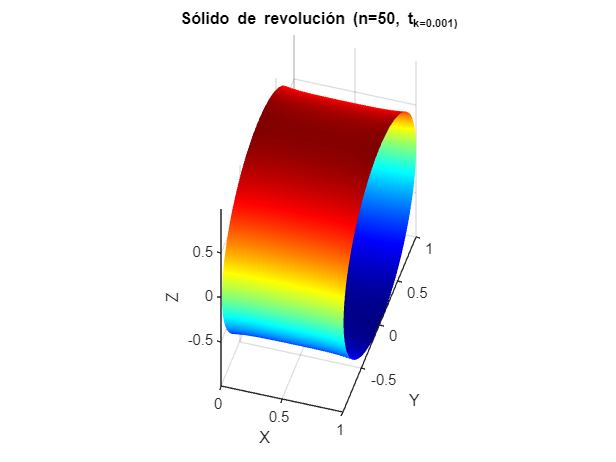

Resultados para n = 50, t_k = 0.001


Punto óptimo (x):


                         1         0.997069648053201         0.994500499090338         0.992260545404152         0.990318916430192         0.988645999101423         0.987213567587208         0.985994911908895         0.984964955803097         0.984100355641228         0.983379574095403         0.982782924398586         0.982292583289533         0.981892572875139          0.98156871352989         0.981308551475807         0.981101265790398         0.980937560266897         0.980809545832288         0.980710619172991         0.980635342898835         0.980579332069157         0.980539151281423         0.980512225841857         0.980496769843807         0.980491733302034         0.980496769843807         0.980512225841857         0.980539151281423         0.980579332069157         0.980635342898835         0.980710619172991         0.980809545832288         0.980937560266897         0.981101265790398         0.981308551475807          0.98156871352989         0.981892572875139         0.9

Valor óptimo de f(x):


         0.966988499166974



Área debajo de la curva:


          0.98459447993331



Número de iteraciones:


        1000



Tiempo en segundos:


               255.9125782



t2n6Iteracion:1
t2n6Iteracion:2
t2n6Iteracion:3
t2n6Iteracion:4
t2n6Iteracion:5
t2n6Iteracion:6
t2n6Iteracion:7
t2n6Iteracion:8
t2n6Iteracion:9
t2n6Iteracion:10
t2n6Iteracion:11
t2n6Iteracion:12
t2n6Iteracion:13
t2n6Iteracion:14
t2n6Iteracion:15
t2n6Iteracion:16
t2n6Iteracion:17
t2n6Iteracion:18
t2n6Iteracion:19
t2n6Iteracion:20
t2n6Iteracion:21
t2n6Iteracion:22
t2n6Iteracion:23
t2n6Iteracion:24
t2n6Iteracion:25
t2n6Iteracion:26
t2n6Iteracion:27
t2n6Iteracion:28
t2n6Iteracion:29
t2n6Iteracion:30
t2n6Iteracion:31
t2n6Iteracion:32
t2n6Iteracion:33
t2n6Iteracion:34
t2n6Iteracion:35
t2n6Iteracion:36
t2n6Iteracion:37
t2n6Iteracion:38
t2n6Iteracion:39
t2n6Iteracion:40
t2n6Iteracion:41
t2n6Iteracion:42
t2n6Iteracion:43
t2n6Iteracion:44
t2n6Iteracion:45
t2n6Iteracion:46
t2n6Iteracion:47
t2n6Iteracion:48
t2n6Iteracion:49
t2n6Iteracion:50
t2n6Iteracion:51
t2n6Iteracion:52
t2n6Iteracion:53
t2n6Iteracion:54
t2n6Iteracion:55
t2n6Iteracion:56
t2n6Iteracion:57
t2n6Iteracion:58
t2n6Iteracion:59
t2n6It

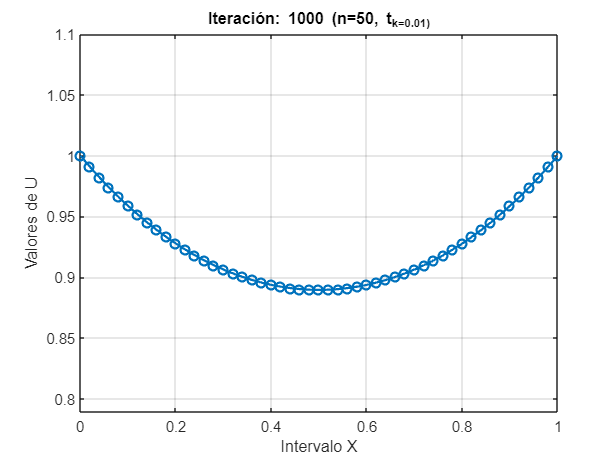

Área debajo de la curva (n=50, t_k=0.01): 0.9254


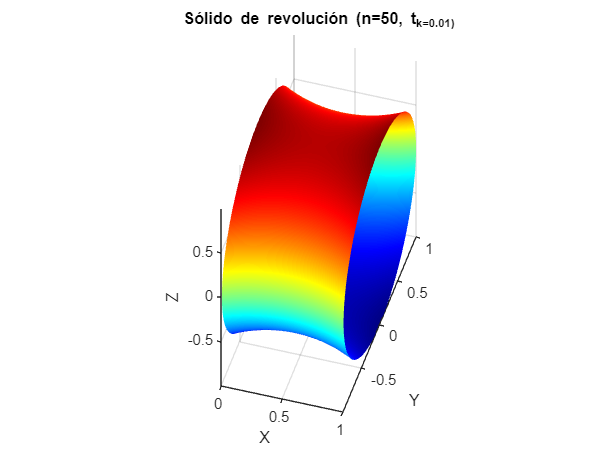

Resultados para n = 50, t_k = 0.01


Punto óptimo (x):


                         1         0.990819296406632         0.982099136384771         0.973827735193683         0.965994071229545         0.958587840484068         0.951599415669644          0.94501980961163         0.938840642536944         0.933054112915678         0.927652971538602         0.922630498537928          0.91798048308162         0.913697205492829         0.909775421565955         0.906210348869443         0.902997654843029         0.900133446513885         0.897614261672185          0.89543706136222         0.893599223560459         0.892098537927042         0.890933201532181         0.890101815473934         0.889603382318853         0.889437304312106         0.889603382318853         0.890101815473934         0.890933201532181         0.892098537927042         0.893599223560459          0.89543706136222         0.897614261672185         0.900133446513885         0.902997654843029         0.906210348869443         0.909775421565955         0.913697205492829          0.

Valor óptimo de f(x):


         0.938861323498684



Área debajo de la curva:


         0.925401049075152



Número de iteraciones:


        1000



Tiempo en segundos:


               252.3283535



t3n6Iteracion:1
t3n6Iteracion:2
t3n6Iteracion:3
t3n6Iteracion:4
t3n6Iteracion:5
t3n6Iteracion:6
t3n6Iteracion:7
t3n6Iteracion:8
t3n6Iteracion:9
t3n6Iteracion:10
t3n6Iteracion:11
t3n6Iteracion:12
t3n6Iteracion:13
t3n6Iteracion:14
t3n6Iteracion:15
t3n6Iteracion:16
t3n6Iteracion:17
t3n6Iteracion:18
t3n6Iteracion:19
t3n6Iteracion:20
t3n6Iteracion:21
t3n6Iteracion:22
t3n6Iteracion:23
t3n6Iteracion:24
t3n6Iteracion:25
t3n6Iteracion:26
t3n6Iteracion:27
t3n6Iteracion:28
t3n6Iteracion:29
t3n6Iteracion:30
t3n6Iteracion:31
t3n6Iteracion:32
t3n6Iteracion:33
t3n6Iteracion:34
t3n6Iteracion:35
t3n6Iteracion:36
t3n6Iteracion:37
t3n6Iteracion:38
t3n6Iteracion:39
t3n6Iteracion:40
t3n6Iteracion:41
t3n6Iteracion:42
t3n6Iteracion:43
t3n6Iteracion:44
t3n6Iteracion:45
t3n6Iteracion:46
t3n6Iteracion:47
t3n6Iteracion:48
t3n6Iteracion:49
t3n6Iteracion:50
t3n6Iteracion:51
t3n6Iteracion:52
t3n6Iteracion:53
t3n6Iteracion:54
t3n6Iteracion:55
t3n6Iteracion:56
t3n6Iteracion:57
t3n6Iteracion:58
t3n6Iteracion:59
t3n6It

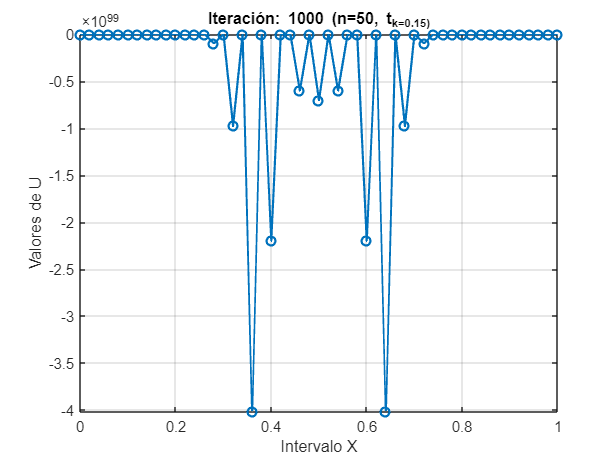

Área debajo de la curva (n=50, t_k=0.15): -3.296452302411122e+98


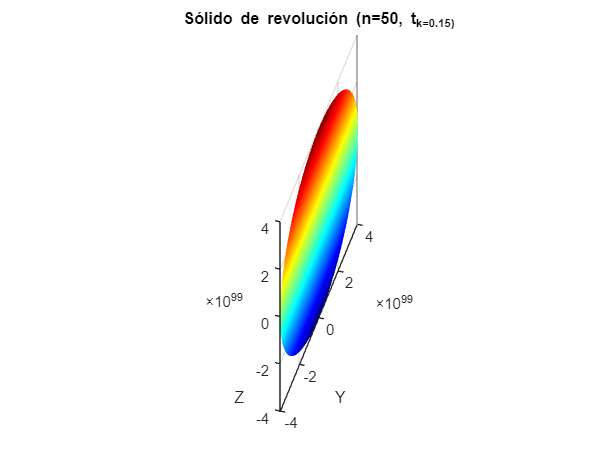

Resultados para n = 50, t_k = 0.15


Punto óptimo (x):


                         1         0.912214470469172         0.829141652106824         0.722799326896736         0.580162328641665          -73052.181949264      2.71319073367391e+21     -2.50426195397477e+38      1.52014117565851e+55      1.15448933671803e+71     -8.71235028011145e+88      8.61312490604268e+78     -5.26330703529208e+95      -1.7597802333382e+81      -9.9097411510893e+97      4.72173962730747e+81     -9.74842452199843e+98     -7.44990904788409e+82      -4.0153281937854e+99     -6.49168377747016e+82     -2.19825930291092e+99      6.53974042768525e+81     -1.68315200195774e+82     -6.00743184263973e+98     -1.54971260355532e+82     -7.04667761139515e+98      6.51450474309715e+81     -6.00743184256827e+98      1.65967874823525e+81      4.62129941829362e+82     -2.19825930291091e+99       1.5922978287591e+82     -4.01532819378534e+99     -3.11269222541831e+82     -9.74842452199799e+98     -1.95260793711647e+82     -9.90974115108856e+97     -8.26256278282873e+80     -5.2633

Valor óptimo de f(x):


    -4.50490270949504e+199



Área debajo de la curva:


     -3.29645230241112e+98



Número de iteraciones:


        1000



Tiempo en segundos:


               266.3288166



clear all;
format longg;

%% Configuración de barridos
n_values = [5, 10, 15, 20, 25, 50]; % Valores de n
t_values = [0.001, 0.01,0.15]; % Valores de t_k

% Para guardar los resultados de cada barrido
resultados = struct();
figure_count = 1; % Contador de figuras para evitar sobreescritura

% Crear carpeta para guardar resultados
output_folder = 'resultados';
if ~exist(output_folder, 'dir')
    mkdir(output_folder);
end

%% Barrido de parámetros
for n_idx = 1:length(n_values)
    for t_idx = 1:length(t_values)
        % Definir parámetros actuales
        n = n_values(n_idx);
        t_k = t_values(t_idx);

        %% Paso 1: Inicializar el algoritmo
        x0 = 0;
        xn = 1;
        Xinit = linspace(x0, xn, n+1); % Iniciamos en el origen
        Uinit = ones(1, n+1); % Iniciamos en el origen
        u0 = 1;
        un = 1;

        delta = 1e-5; % Tolerancia para la convergencia
        max_iter = 1000; % Número máximo de iteraciones
        iter = 0;

        % Inicializar errores
        error_1 = delta + 1;
        error_2 = delta + 1;
        x_k = Uinit;
        x_hist = x_k';

        % Inicializar tabla para guardar los resultados por iteración
        tabla_iteraciones = [];
        % superior_0 = true; % Condición para evitar valores menores que 0

        % Preparar grabación de video
        video_filename = fullfile(output_folder, sprintf('gradiente_n%d_t%.3f.mp4', n, t_k));
        video_writer = VideoWriter(video_filename, 'MPEG-4');
        open(video_writer);

        %% Implementación del Método del Gradiente Descendente
        tic
        while (error_1 > delta || error_2 > delta) && iter < max_iter
            iter = iter + 1;

            %% Paso 2: Calcular el gradiente en el punto actual
            gradiente = compute_gk(x_k);
            
            %% Calculamos las Tj de cada x_k
            % Tj(iter, :) = calcularT(x_k);
            % T_suma(iter) = compute_T_and_sum(x_k);

            %% Paso 3: Actualizar el punto usando el gradiente descendente
            x_k_plus_1 = x_k - t_k .* gradiente;
            x_k_plus_1(1) = 1; x_k_plus_1(n+1) = 1; % exijo las condiciones de contorno!!!

            %% Calcular los errores
            error_1 = norm(x_k_plus_1 - x_k);
            error_2 = norm(compute_gk(x_k_plus_1));

            %% Guardar resultados en cada iteración
            tabla_iteraciones = [tabla_iteraciones; iter, x_k, compute_T_and_sum(x_k), error_1, error_2];

            % Actualizar x_k y guardar el historial
            x_k = x_k_plus_1;
            x_hist = [x_hist; x_k'];


            % Gráfico 2D de X vs U (Figura 1)
            figure(figure_count); % Crear una figura nueva para evitar sobreescritura
            
            x_values = linspace(x0, xn, n+1);
            
            % Graficar puntos discretos
            plot(x_values, x_k, '-o', 'LineWidth', 1.5)
            grid on;
            title(['Iteración: ', num2str(iter), ' (n=', num2str(n), ', t_k=', num2str(t_k), ')']);
            xlabel('Intervalo X');
            ylabel('Valores de U');
            xlim([x0 xn]);
            ylim([min(x_k) - 0.1, max(x_k) + 0.1]); % Ajustar los límites de Y dinámicamente
            pause(0.1); % Pausa para animación

            % Guardar frame en el video
            frame = getframe(gcf);
            writeVideo(video_writer, frame);
            disp(['t',num2str(t_idx),'n',num2str(n_idx),'Iteracion:',num2str(iter)])
        end

        %% Calcular el área debajo de la curva
        area_debajo_curva = trapz(x_values, x_k);
        disp(['Área debajo de la curva (n=', num2str(n), ', t_k=', num2str(t_k), '): ', num2str(area_debajo_curva)]);

        %% Gráfico final de X vs U (Figura 2)
        figure_count = figure_count + 1; % Incrementar el número de figura
        figure(figure_count);
        plot(x_values, x_k, '-o', 'LineWidth', 1.5);
        grid on;
        title(['Iteración: ', num2str(iter), ' (n=', num2str(n), ', t_k=', num2str(t_k), ')']);
        xlabel('Intervalo X');
        ylabel('Valores de U');
        xlim([x0 xn]);
        ylim([min(x_k) - 0.1, max(x_k) + 0.1]); % Ajustar los límites de Y dinámicamente

        % Guardar la figura
        saveas(gcf, fullfile(output_folder, sprintf('final_n%d_t%.3f.pdf', n, t_k)));

        %% Sólido de revolución (Figura 3)
        figure_count = figure_count + 1; % Incrementar el número de figura
        theta = linspace(0, 2*pi, 100); % Ángulo de revolución
        [X, T] = meshgrid(x_values, theta);
        U = x_k; % Usar los valores originales de U sin interpolación
        R = repmat(U, size(T, 1), 1); % Repetir U para todas las rotaciones
        Y = R .* cos(T); % Coordenada Y
        Z = R .* sin(T); % Coordenada Z

        figure(figure_count);
        surf(X, Y, Z, 'EdgeColor', 'none'); % Gráfico 3D
        colormap('jet');
        shading interp;
        title(['Sólido de revolución (n=', num2str(n), ', t_k=', num2str(t_k), ')']);
        xlabel('X');
        ylabel('Y');
        zlabel('Z');
        axis equal;
        grid on;
        view([16.60 45.82]);

        % Guardar la figura
        saveas(gcf, fullfile(output_folder, sprintf('solid_n%d_t%.3f.pdf', n, t_k)));

        % Cerrar video
        close(video_writer);

        %% Guardar los resultados del barrido
        x_opt = x_k;
        f_opt = compute_T_and_sum(x_k);
        elapsedTime = toc;

        resultados.(['n_' num2str(n) '_t_' strrep(num2str(t_k), '.', '_')]) = struct(...
            'x_opt', x_opt, ...
            'f_opt', f_opt, ...
            'area', area_debajo_curva, ...
            'iter', iter, ...
            'elapsedTime', elapsedTime, ...
            'tabla_iteraciones', tabla_iteraciones ...
        );

        %% Mostrar resultados parciales
        disp(['Resultados para n = ' num2str(n) ', t_k = ' num2str(t_k)]);
        disp('Punto óptimo (x):');
        disp(x_opt);
        disp('Valor óptimo de f(x):');
        disp(f_opt);
        disp('Área debajo de la curva:');
        disp(area_debajo_curva);
        disp('Número de iteraciones:');
        disp(iter);
        disp('Tiempo en segundos:');
        disp(elapsedTime);
        figure_count = figure_count + 1; % Incrementar el contador de figuras
    end
    clear T_suma;
    clear Tj;
end


%% Mostrar resultados finales
disp('Resultados del barrido:');

Resultados del barrido:


disp(resultados);

     n_5_t_0_001: [1×1 struct]
      n_5_t_0_01: [1×1 struct]
      n_5_t_0_15: [1×1 struct]
    n_10_t_0_001: [1×1 struct]
     n_10_t_0_01: [1×1 struct]
     n_10_t_0_15: [1×1 struct]
    n_15_t_0_001: [1×1 struct]
     n_15_t_0_01: [1×1 struct]
     n_15_t_0_15: [1×1 struct]
    n_20_t_0_001: [1×1 struct]
     n_20_t_0_01: [1×1 struct]
     n_20_t_0_15: [1×1 struct]
    n_25_t_0_001: [1×1 struct]
     n_25_t_0_01: [1×1 struct]
     n_25_t_0_15: [1×1 struct]
    n_50_t_0_001: [1×1 struct]
     n_50_t_0_01: [1×1 struct]
     n_50_t_0_15: [1×1 struct]



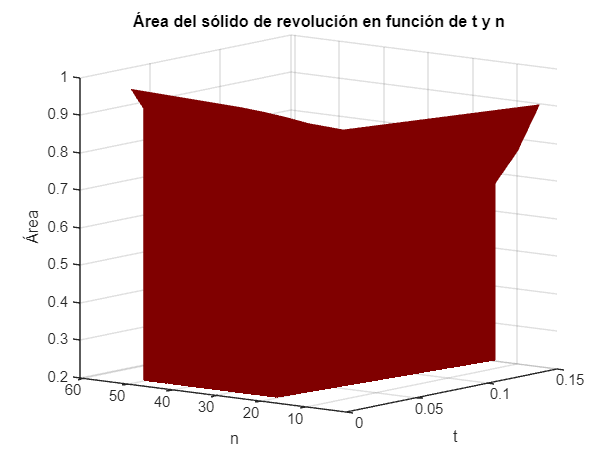

%Gráfico 3D

% Matriz para guardar las áreas extraídas
areas = zeros(length(n_values), length(t_values));

% Extraer las áreas de la estructura 'resultados'
for n_idx = 1:length(n_values)
    for t_idx = 1:length(t_values)
        % Construir el nombre del campo en la estructura 'resultados'
        n = n_values(n_idx);
        t = t_values(t_idx);
        field_name = ['n_' num2str(n) '_t_' strrep(num2str(t), '.', '_')];
        
        % Extraer el área correspondiente
        if isfield(resultados, field_name)
            areas(n_idx, t_idx) = resultados.(field_name).area;
        else
            areas(n_idx, t_idx) = NaN; % Manejar casos donde el campo no existe
        end
    end
end

% Crear el gráfico 3D
[T_grid, N_grid] = meshgrid(t_values, n_values); % Crear la malla para t y n
figure;
surf(T_grid, N_grid, areas); % Graficar la superficie
colormap('jet');
shading interp;
xlabel('t');
ylabel('n');
zlabel('Área');
title('Área del sólido de revolución en función de t y n');
grid on;

xlim([0.000 0.150])
ylim([1.0 61.0])
zlim([0.200 1.000])
view([-51.682 10.364])

% Exportar el gráfico a un archivo PDF
output_filename = '3dplot_area.pdf'; % Nombre del archivo de salida
set(gcf, 'PaperPositionMode', 'auto'); % Ajustar para exportar como aparece en pantalla
print('-dpdf', output_filename); % Exportar a PDF

disp(['El gráfico se ha exportado a: ', output_filename]);

El gráfico se ha exportado a: 3dplot_area.pdf


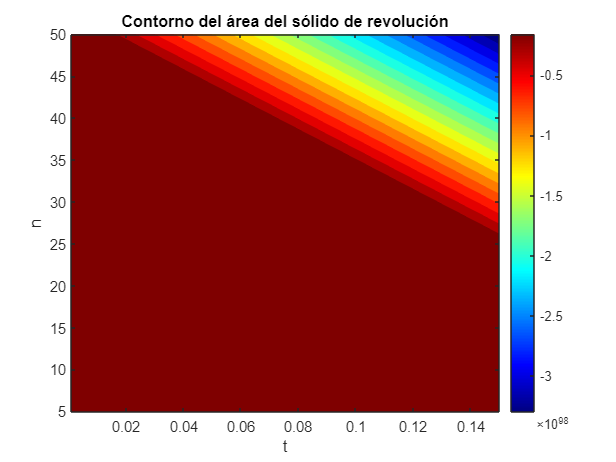

%Gráfico de contorno

% Inicializar valores para el barrido
n_values = [5, 10, 15, 20, 25, 50]; % Valores de n
t_values = [0.15, 0.01, 0.001]; % Valores de t_k

% Matriz para guardar las áreas extraídas
areas = zeros(length(n_values), length(t_values));

% Extraer las áreas de la estructura 'resultados'
for n_idx = 1:length(n_values)
    for t_idx = 1:length(t_values)
        % Construir el nombre del campo en la estructura 'resultados'
        n = n_values(n_idx);
        t = t_values(t_idx);
        field_name = ['n_' num2str(n) '_t_' strrep(num2str(t), '.', '_')];
        
        % Extraer el área correspondiente
        if isfield(resultados, field_name)
            areas(n_idx, t_idx) = resultados.(field_name).area;
        else
            areas(n_idx, t_idx) = NaN; % Manejar casos donde el campo no existe
        end
    end
end

% Crear un contour plot
[T_grid, N_grid] = meshgrid(t_values, n_values); % Crear la malla para t y n
figure;
contourf(T_grid, N_grid, areas, 20, 'LineColor', 'none'); % Contour plot con 20 niveles
colormap('jet');
colorbar; % Mostrar la barra de colores
xlabel('t');
ylabel('n');
title('Contorno del área del sólido de revolución');

% Exportar el gráfico a un archivo PDF
output_filename = 'contourplot_area.pdf'; % Nombre del archivo de salida
set(gcf, 'PaperPositionMode', 'auto'); % Ajustar para exportar como aparece en pantalla
print('-dpdf', output_filename); % Exportar a PDF

disp(['El gráfico se ha exportado a: ', output_filename]);

El gráfico se ha exportado a: contourplot_area.pdf


**Función calcula g**

function gk_vector = compute_gk(u)
    % Entradas:
    % n - Número total de segmentos
    % u - Array de valores de u (longitud n+1)
    % u0 - Valor inicial de u
    % un - Valor final de u
    
    % Salida:
    % gk_vector - Vector del gradiente calculado

    % Asignar valores iniciales y finales
    % u(1) = u0;
    % u(n) = un;

    % Inicializar el vector gk de longitud n
    n=length(u);
    gk_vector = zeros(1, length(u));

    % Calcular los valores de gk
    for k = 1:n
        if k == 1
            % Caso k = 1
            % gk_vector(k) = (1/(2*n)) * (sqrt(1 + n^2 * (u(2) - u(1))^2) - ...
            %                             n^2 * (u(2) - u(1)) * (u(2) + u(1)) / sqrt(1 + n^2 * (u(2) - u(1))^2));
            gk_vector(k) = ((1/(2*n))-(n/2*u(1)*(u(2)-u(1)))/ sqrt(1 + n^2 * (u(2) - u(1))^2));
        elseif k == n
            % Caso k = n
            % gk_vector(k) = (1/(2*n)) * (n^2 * (u(n) - u(n-1)) * (u(n-1) + u(n)) / sqrt(1 + n^2 * (u(n) - u(n-1))^2) + ...
            %                             sqrt(1 + n^2 * (u(n) - u(n-1))^2));

            gk_vector(k) = ((n/2 * (u(n) - u(n-1)) * (u(n-1) + u(n))+ (1/(2*n)))/sqrt(1 + n^2 * (u(n) - u(n-1))^2));
        else
            % Caso 2 <= k <= n-1
            gk_vector(k) = (1/(2*n)) * (n^2 * (u(k) - u(k-1)) * (u(k-1) + u(k)) / sqrt(1 + n^2 * (u(k) - u(k-1))^2) + ...
                                        sqrt(1 + n^2 * (u(k) - u(k-1))^2) + ...
                                        sqrt(1 + n^2 * (u(k+1) - u(k))^2) - ...
                                        n^2 * (u(k+1) - u(k)) * (u(k) + u(k+1)) / sqrt(1 + n^2 * (u(k+1) - u(k))^2));
        end
    end
end



% function T_sum = compute_Tj_sum(u)
%     % Entradas:
%     % n - Número total de segmentos
%     % u - Array de valores de u (longitud n+1)
%     % u0 - Valor inicial de u
%     % un - Valor final de u
% 
%     % Inicializar la suma
%     T_sum = 0;
%     n=length(u);
% 
%     % Calcular la suma de los Tj
%     for j = 1:n-1
%         Tj = ((u(j) + u(j+1)) * sqrt(1 + n^2 * (u(j+1) - u(j))^2)) / (2 * n);
%         T_sum = T_sum + Tj;
%     end
% 
%     % disp('Suma de Tj calculada:');
%     % disp(T_sum);
% end
% 
% function headers = create_headers_list(n)
%     % Crear las etiquetas dinámicas dependiendo de n
%     headers = [{'Iteración'}, arrayfun(@(x) sprintf('x_%d', x), 1:n, 'UniformOutput', false), {['' ...
%         'T'], 'Error_1', 'Error_2'}];
% 
%     disp('Lista de encabezados creada:');
%     disp(headers);
% end
% 
% function T = calcularT(u)
%     % Entrada:
%     % u: vector de valores [u_j, u_{j+1}, ...]
%     % n: entero que define la fórmula
% 
%     % Verifica que el vector u tenga al menos dos elementos
%     if length(u) < 2
%         error('El vector u debe tener al menos dos elementos.');
%     end
% 
%     % Inicializa el vector de salida
%     T = zeros(1, length(u) - 1);
%     n=length(u);
% 
%     % Calcula T_j para cada par de valores consecutivos en u
%     for j = 1:length(u) - 1
%         uj = u(j);
%         uj1 = u(j + 1);
%         T(j) = (1 / (2 * (n + 1))) * ...
%                (uj1 + uj) * ...
%                sqrt(1 + (n + 1)^2 * (uj1 - uj)^2);
%     end
% end

function [T_sum, T] = compute_T_and_sum(u)
    % Entradas:
    % u - Vector de valores [u_j, u_{j+1}, ...]
    % Salidas:
    % T_sum - Suma total de los valores T_j
    % T - Vector de los valores T_j
    
    % Verificar que el vector u tenga al menos dos elementos
    if length(u) < 2
        error('El vector u debe tener al menos dos elementos.');
    end

    % Inicializar parámetros
    n = length(u); % Número de segmentos
    T = zeros(1, n - 1); % Vector para almacenar los T_j
    T_sum = 0; % Inicializar la suma

    % Calcular T_j y acumular en T_sum
    for j = 1:n-1
        uj = u(j);
        uj1 = u(j + 1);
        T(j) = (1 / (2 * (n))) * (uj1 + uj) * sqrt(1 + (n)^2 * (uj1 - uj)^2);
        T_sum = T_sum + T(j); % Acumular la suma
    end
end

